%Part 1
%Non-Linear Propogation of states
dt = 0.1;
L = 0.5;
t = 0:dt:100;
n = length(t);
xnom = [10;0;pi/2;-60;0;-pi/2];
dx0 =  [0;1;0;0;0;0.1];
%dx0 = [1;0;0.1;6;0.1;0.1];
unom = [2,-pi/18, 12, pi/25];
%options = odeset('RelTol', 1e-12);
xdot = @(x, u)[u(1)*cos(x(3)); u(1)*sin(x(3));u(1)*tan(u(2))/L;u(3)*cos(x(6));u(3)*sin(x(6));u(4)];
xdotwrap = @(t, x) xdot(x, [2,-pi/18, 12, pi/25]);

ynl = function_handle with value:
    @(x)[atan((x(5)-x(2))/(x(1)-x(4)))-x(3);sqrt((x(1)-x(4))^2+(x(2)-x(5))^2);atan((x(2)-x(5))/(x(4)-x(1)))-x(6);x(4);x(5)]



xold = xnom;
xmat = [];
delxold = dx0;
delxmat = [];
ydall = [];
yfmat = [];
ytota = [];
for i = 0:dt:100

    [tode, y] = ode45(xdotwrap, [0 dt], xold);
    xnew = y(end, :);
    xnew(3) = constrainAngle(xnew(3));
    xnew(6) = constrainAngle(xnew(6));
    xmat = [xmat; xnew];
    xold = xnew;

    [F, G, H] = linStateMats(xnew, unom, L, dt);
    delxnew = F*delxold;
    delxmat = [delxmat delxnew];
    delxold = delxnew;

    yfvar = getY(xnew');
    yfdall = H*delxnew;
    ytot = yfvar + yfdall;
    ytot(1) = constrainAngle(ytot(1));
    ytot(3) = constrainAngle(ytot(3));
    yfvar(1) = constrainAngle(yfvar(1));
    yfvar(3) = constrainAngle(yfvar(3));
    ytota = [ytota ytot];
    yfmat = [yfmat yfvar];
end
yfmat

yfmat =     1.6613    1.7518    1.8422    1.9326    2.0228    2.1128    2.2027    2.2924    2.3819    2.4711    2.5600    2.6486    2.7370    2.8251    2.9128    3.0003    3.0874   -3.1090   -3.0225   -2.9363   -2.8505   -2.7649   -2.6796   -2.5945   -2.5097   -2.4252   -2.3409   -2.2568   -2.1729   -2.0891   -2.0055   -1.9221   -1.8387   -1.7554   -1.6723   -1.5891   -1.5060   -1.4229   -1.3398   -1.2566   -1.1735   -1.0902   -1.0069   -0.9234   -0.8398   -0.7561   -0.6723   -0.5883   -0.5041   -0.4197
   70.0135   70.0539   70.1210   70.2142   70.3328   70.4762   70.6431   70.8326   71.0432   71.2736   71.5222   71.7874   72.0674   72.3605   72.6648   72.9785   73.2996   73.6262   73.9565   74.2887   74.6208   74.9512   75.2780   75.5998   75.9149   76.2218   76.5193   76.8060   77.0808   77.3426   77.5906   77.8240   78.0421   78.2444   78.4305   78.6001   78.7531   78.8896   79.0097   79.1136   79.2017   79.2747   79.3332   79.3779   79.4098   79.4300   79.4394   79.4393   79.4312 

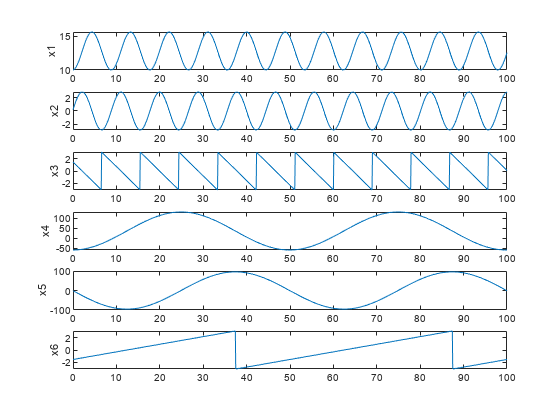

%q1 NL plots for x
figure(1)
subplot(6,1,1),plot(t, xmat(:,1)),ylabel('x1');
subplot(6,1,2),plot(t, xmat(:,2)),ylabel('x2');
subplot(6,1,3),plot(t, xmat(:,3)),ylabel('x3');
subplot(6,1,4),plot(t, xmat(:,4)),ylabel('x4');
subplot(6,1,5),plot(t, xmat(:,5)),ylabel('x5');
subplot(6,1,6),plot(t, xmat(:,6)),ylabel('x6');

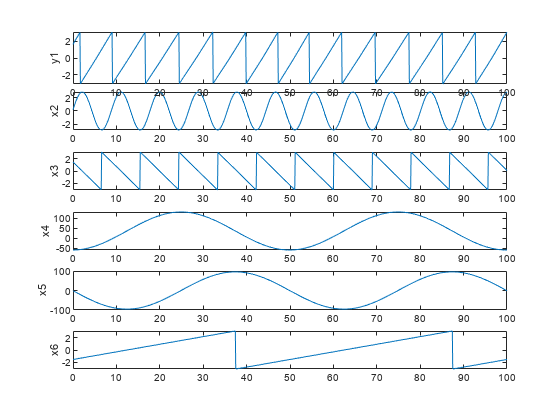


%q1 NL plots for y
figure(2)
subplot(5,1,1),plot(t,yfmat(1,:)), ylabel("y1");

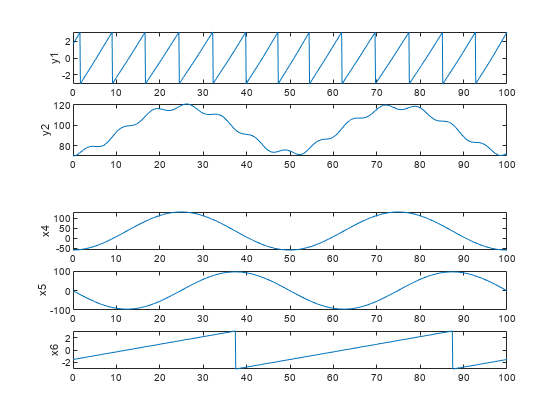

subplot(5,1,2),plot(t,yfmat(2,:)), ylabel("y2");

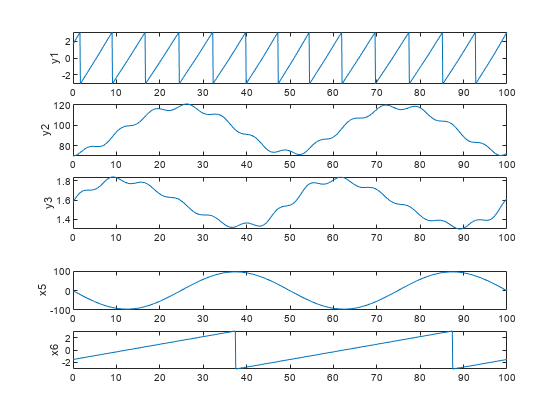

subplot(5,1,3),plot(t,yfmat(3,:)), ylabel("y3");

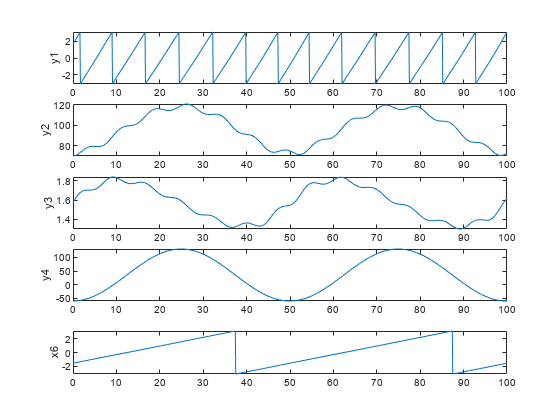

subplot(5,1,4),plot(t,yfmat(4,:)), ylabel("y4");

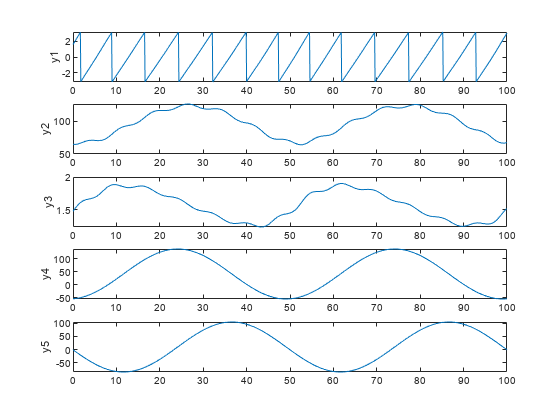

subplot(5,1,5),plot(t,yfmat(5,:)), ylabel("y5");


%linearized plots

%plots for linearized y
figure(3)
subplot(5,1,1),plot(t,ytota(1,:)), ylabel("y1");
subplot(5,1,2),plot(t,ytota(2,:)), ylabel("y2");
subplot(5,1,3),plot(t,ytota(3,:)), ylabel("y3");
subplot(5,1,4),plot(t,ytota(4,:)), ylabel("y4");
subplot(5,1,5),plot(t,ytota(5,:)), ylabel("y5");

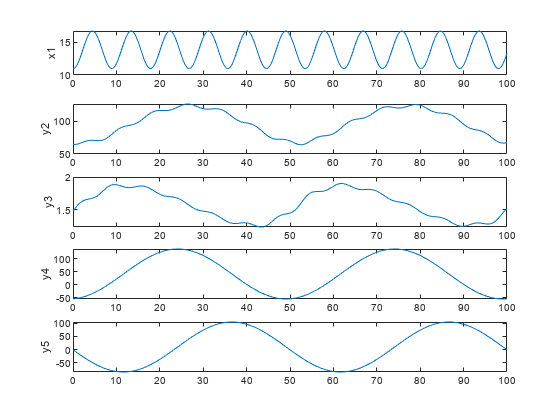



%plots for linearized total x
xfull = xmat + delxmat';
figure(4)
subplot(6,1,1),plot(t, xfull(:,1)),ylabel('x1');

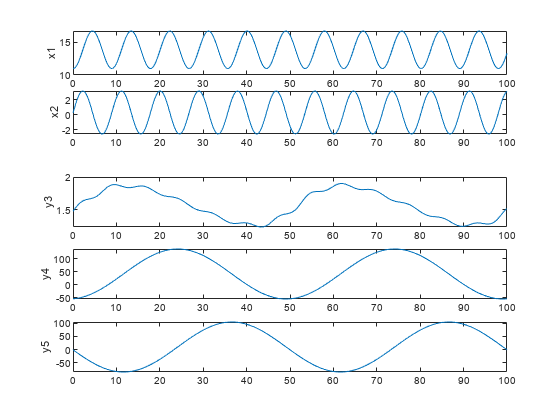

subplot(6,1,2),plot(t, xfull(:,2)),ylabel('x2');

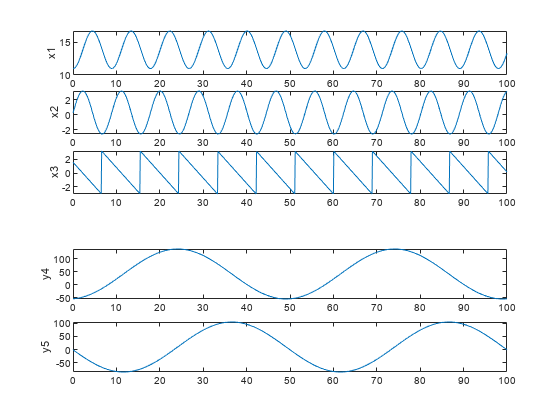

subplot(6,1,3),plot(t, xfull(:,3)),ylabel('x3');

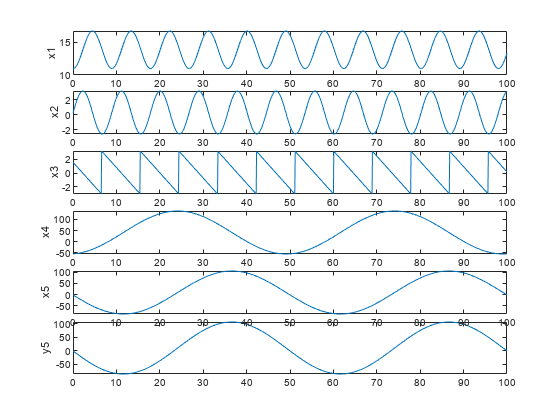

subplot(6,1,4),plot(t, xfull(:,4)),ylabel('x4');
subplot(6,1,5),plot(t, xfull(:,5)),ylabel('x5');

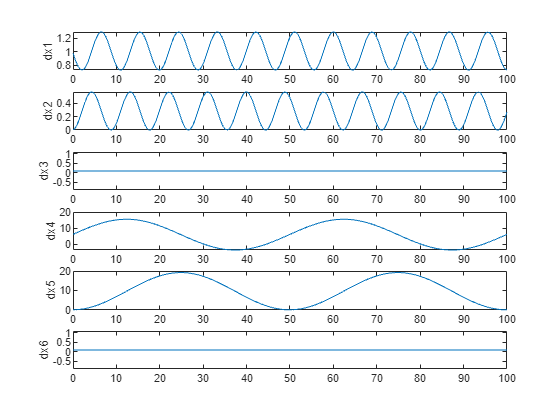

subplot(6,1,6),plot(t, xfull(:,6)),ylabel('x6');

%plots for perturbations
figure(5)
subplot(6,1,1),plot(t, delxmat(1,:)),ylabel('dx1');
subplot(6,1,2),plot(t, delxmat(2,:)),ylabel('dx2');
subplot(6,1,3),plot(t, delxmat(3,:)),ylabel('dx3');
subplot(6,1,4),plot(t, delxmat(4,:)),ylabel('dx4');
subplot(6,1,5),plot(t, delxmat(5,:)),ylabel('dx5');
subplot(6,1,6),plot(t, delxmat(6,:)),ylabel('dx6');




% legend('x1', 'x2', 'x3', 'x4', 'x5', 'x6')

%Q5
% Linearized Kalman Filter
%dx0 = [0;0;0.1;0;0;0.1]; %3
dx0 =  [0;1;0;0;0;0.1];
x0 = xnom;
N = 50; % number of monte carlo simulations
%LKF
rng(100);
for j = 1:N
    xwn = [];
    ywn = [];
    Rkf = Rtrue; %1
    %Qkf = 0.5*Qtrue; %2
    %Qkf = diag([0.005*0.001,0.01*0.001,0.01*0.01,10*0.001,30*0.001,0.01*0.01]);
    Q_ek = diag([500*0.001,500*0.001,10*0.1,5000,500*1,10*0.01]);
    x_all = zeros(6,n);
    x_all(:,1) = dx0;
    sg = dt*eye(6);
    [F, G, H] = linStateMats(xmat(1,:), unom, L, dt);
    xlkt = zeros(6,n);
    xlkt(:,1) = transpose(xmat(1,:)) + x_all(:,1);
    %p = inv(transpose(Hall)*inv(Rall)*Hall);
    p = 5*Qtrue; %4
    x0int = mvnrnd(x0, p);
    nees_samp = zeros(N,n);
    nis_samp = zeros(N,n);
    for i = 0:dt:100
        %Noisy Ground states
        [tode, y1] = ode45(xdotwrap, [0 dt], x0int);
        xn1 = y1(end, :);
        xn1(3) = constrainAngle(xn1(3));
        xn1(6) = constrainAngle(xn1(6));
        xn2 = xn1 + mvnrnd(zeros(1,6), Qtrue);
        xwn = [xwn ;xn2];
        x0int = xn1;
    
        %Noisy Measurements
        yw1 = getY(xn1');
        yw1(1) = constrainAngle(yw1(1));
        yw1(3) = constrainAngle(yw1(3));
        yw1 = yw1 + transpose(mvnrnd(zeros(1,5), Rtrue));
        ywn = [ywn yw1];
    end
    
    
    for i = 1:1000 
        %prediction step
        x_all(:,i+1) = F*x_all(:,i);
        p = F*p*transpose(F) + sg*Qkf*transpose(sg);
        [F, G, H] = linStateMats(xmat(i+1,:), unom, L, dt);
        S = H*p*transpose(H)+Rkf;
        ypred = H*x_all(:,i+1);
        K = p*transpose(H)*inv(H*p*transpose(H)+Rkf);
        %measurement update
        x_all(:,i+1) = x_all(:,i+1) + K*((ywn(:,i)-yfmat(:,i)) - ypred);
        p = (eye(6) - K*H)*p;
        xlkt(:,i+1) = transpose(xmat(i+1,:)) + x_all(:,i+1);

        %NEES/NIS
        S = 0.5*(S+transpose(S));
        nees_samp(j,i) = transpose(transpose(xwn(i,:)) - xlkt(:,i))*inv(p)*(transpose(xwn(i,:)) - xlkt(:,i));
        nis_samp(j,i) = transpose(ywn(:,i)-(ypred+yfmat(:,i)))*inv(S)*(ywn(:,i)-(ypred+yfmat(:,i)));
        
    end
end


%NEES test
nees_bar = mean(nees_samp,1);
alpha_nees = 0.05;
Nnx = N*6;
r1x = chi2inv(alpha_nees/2, Nnx )/ N

r1x = 5.0782

r2x = chi2inv(1-alpha_nees/2, Nnx )/ N

r2x = 6.9975

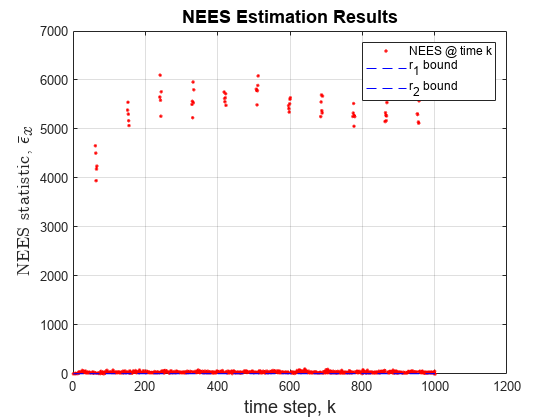


figure(60)
plot(nees_bar,'r.'),hold on
plot(r1x*ones(size(nees_bar)),'b--')
plot(r2x*ones(size(nees_bar)),'b--'),hold off
ylabel('NEES statistic, $\bar{\epsilon}_x$','Interpreter','latex', 'FontSize',14)
xlabel('time step, k','FontSize',14)
title('NEES Estimation Results','FontSize',14)
legend('NEES @ time k', 'r_1 bound', 'r_2 bound'),grid on


%NIS Test
epsNISbar = mean(nis_samp,1);
alphaNIS = 0.05;
Nny = N*5;
%%compute intervals:
r1y = chi2inv(alphaNIS/2, Nny )./ N

r1y = 4.1620

r2y = chi2inv(1-alphaNIS/2, Nny )./ N

r2y = 5.9138

f=figure(90)

f =   Figure (90) with properties:

      Number: 90
        Name: ''
       Color: [1 1 1]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


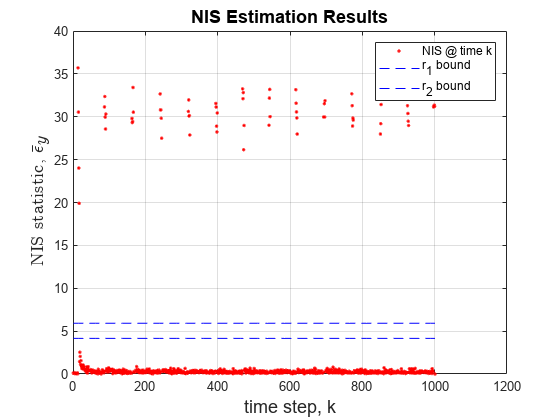

plot(epsNISbar,'r.'),hold on
plot(r1y*ones(size(epsNISbar)),'b--')
plot(r2y*ones(size(epsNISbar)),'b--'),hold off
ylabel('NIS statistic, $\bar{\epsilon}_y$','Interpreter','latex','FontSize',14)
xlabel('time step, k','FontSize',14)
title('NIS Estimation Results','FontSize',14)
legend('NIS @ time k', 'r_1 bound', 'r_2 bound'),grid on


ywn

ywn =     1.8853    2.1704    2.2464    2.4366    2.2777    2.5112    2.8300    2.6904    2.5900    2.8058    2.9691    3.2244    3.0851   -3.3647   -3.1972   -2.7781   -2.5234   -2.8228   -2.3470   -2.2576   -2.5459   -2.1952   -2.3186   -2.3741   -2.2838   -1.9459   -1.9961   -1.7343   -1.9598   -1.5332   -1.7152   -1.6056   -1.4537   -1.4674   -1.3289   -1.2644   -0.9817   -1.3416   -0.6942   -1.2242   -0.7492   -0.3562   -0.4632   -0.4412   -0.4230   -0.2628   -0.1806   -0.1170    0.0637    0.0691
   60.6518   65.8540   88.0845   51.2234   78.2379   68.2915   69.1766   65.6374   66.0131   74.5638   79.7144   68.6564   72.8307   71.2748   63.6772   76.8525   78.9027   78.7936   65.8044   67.2827   90.1166   84.9497   86.5663   83.9427   83.3065   71.3817   81.3705   64.8514   85.5181   71.9061   96.1497   81.3168   72.5990   81.2389   71.3783   84.3857   78.7044   69.2987   99.6846   84.6947   85.5057   79.7852   74.9913   80.2520   84.5933   73.3925   76.0542   66.4934   89.4900   

xwn

xwn =    10.1227    0.1402    1.0926  -59.9820   -1.2160   -1.6463
   10.2213    0.3072    1.1510  -59.9974   -2.4041   -1.5909
   10.3447    0.4867    1.0422  -59.9214   -3.5987   -1.4486
   10.4293    0.6716    0.9446  -59.8828   -4.8506   -1.5309
   10.5800    0.8192    0.8543  -59.8119   -6.0056   -1.6184
   10.6680    0.9413    0.6442  -59.7783   -7.2372   -1.4517
   10.8717    1.0362    0.6898  -59.6024   -8.4888   -1.6627
   10.9789    1.1592    0.6179  -59.5651   -9.6221   -1.6180
   11.1927    1.2454    0.6613  -59.4334  -10.8067   -1.4631
   11.3176    1.3804    0.4725  -59.2710  -12.0538   -1.5575


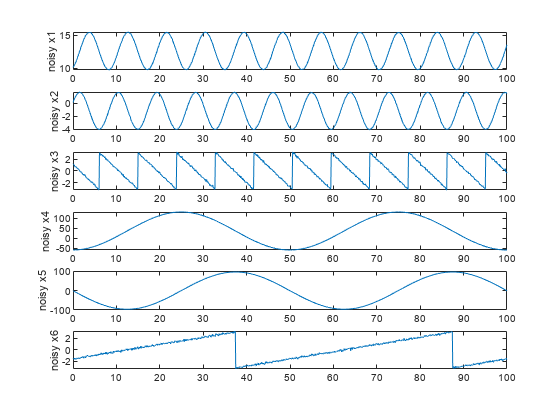


%plot noisy ground truth and measurements
figure(7)
subplot(6,1,1),plot(t, xwn(:,1)),ylabel('noisy x1');
subplot(6,1,2),plot(t, xwn(:,2)),ylabel('noisy x2');
subplot(6,1,3),plot(t, xwn(:,3)),ylabel('noisy x3');
subplot(6,1,4),plot(t, xwn(:,4)),ylabel('noisy x4');
subplot(6,1,5),plot(t, xwn(:,5)),ylabel('noisy x5');
subplot(6,1,6),plot(t, xwn(:,6)),ylabel('noisy x6');

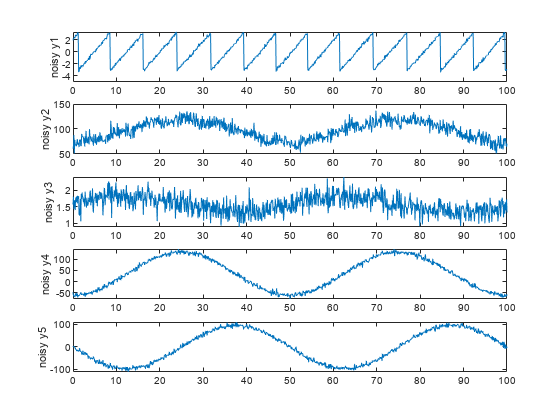


figure(8)
subplot(5,1,1),plot(t, ywn(1,:)),ylabel('noisy y1');
subplot(5,1,2),plot(t, ywn(2,:)),ylabel('noisy y2');
subplot(5,1,3),plot(t, ywn(3,:)),ylabel('noisy y3');
subplot(5,1,4),plot(t, ywn(4,:)),ylabel('noisy y4');
subplot(5,1,5),plot(t, ywn(5,:)),ylabel('noisy y5');

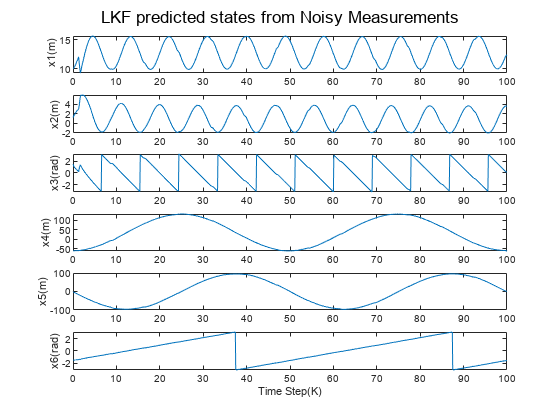



figure(9)
subplot(6,1,1),plot(t, xlkt(1,:)),ylabel(' x1(m)');
subplot(6,1,2),plot(t, xlkt(2,:)),ylabel('x2(m)');
subplot(6,1,3),plot(t, xlkt(3,:)),ylabel('x3(rad)');
subplot(6,1,4),plot(t, xlkt(4,:)),ylabel('x4(m)');
subplot(6,1,5),plot(t, xlkt(5,:)),ylabel('x5(m)');
subplot(6,1,6),plot(t, xlkt(6,:)),ylabel('x6(rad)');
xlabel('Time Step(K)');
sgtitle("LKF predicted states from Noisy Measurements");

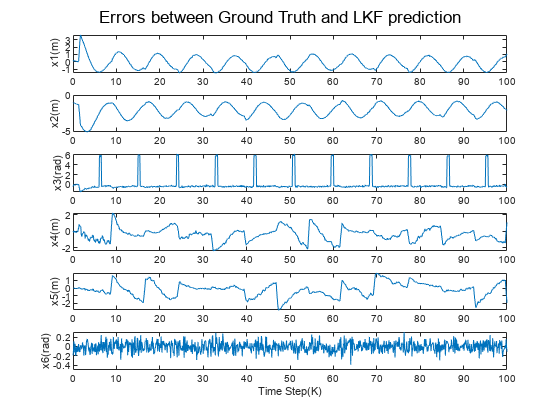


figure(10)
subplot(6,1,1),plot(t,xwn(:,1)'-xlkt(1,:)),ylabel(' x1(m)');
subplot(6,1,2),plot(t, xwn(:,2)'-xlkt(2,:)),ylabel('x2(m)');
subplot(6,1,3),plot(t, xwn(:,3)'-xlkt(3,:)),ylabel('x3(rad)');
subplot(6,1,4),plot(t,xwn(:,4)'-xlkt(4,:)),ylabel('x4(m)');
subplot(6,1,5),plot(t, xwn(:,5)'-xlkt(5,:)),ylabel('x5(m)');
subplot(6,1,6),plot(t,xwn(:,6)'-xlkt(6,:)),ylabel('x6(rad)');
xlabel('Time Step(K)');
sgtitle('Errors between Ground Truth and LKF prediction');

%Q6
%EKF
dt = 0.1;
L = 0.5;
t = 0:dt:100;
n = length(t);
xnom = [10;0;pi/2;-60;0;-pi/2];
%dx0 =  [0;1;0;0;0;0.1];
dx0 = [1;0;0.1;6;0.1;0.1];
unom = [2,-pi/18, 12, pi/25];
%options = odeset('RelTol', 1e-12);
xdot = @(x, u)[u(1)*cos(x(3)); u(1)*sin(x(3));u(1)*tan(u(2))/L;u(3)*cos(x(6));u(3)*sin(x(6));u(4)];
xdotwrap = @(t, x) xdot(x, [2,-pi/18, 12, pi/25]);



N = 50;
rng(100);
for j = 1:N
    xwn = [];
    ywn = [];
    p_ek = 5*Qtrue; %
    x0int = mvnrnd(x0, p_ek);
    x0ek = xnom;
    x_ekf = zeros(6,n);
    x_ekf(:,1) = x0ek;
    p_a = zeros(6,n);
    p_a(:,1) = diag(p_ek);
    sg = dt*eye(6);
    %Q_ek = 50*Qtrue; %
    Q_ek = diag([50*0.001,50*0.001,0.01,5000,500*1,10*0.01]);
    [F, G, H] = linStateMats(x0ek, unom, L, dt);
    Rkf2 = Rtrue; %
    nees_samp = zeros(N,n);
    nis_samp = zeros(N,n);
    for i = 0:dt:100
        %Noisy Ground states
        [tode, y1] = ode45(xdotwrap, [0 dt], x0int);
        xn1 = y1(end, :);
        xn1(3) = constrainAngle(xn1(3));
        xn1(6) = constrainAngle(xn1(6));
        xn2 = xn1 + mvnrnd(zeros(1,6), Qtrue);
        xwn = [xwn ;xn2];
        x0int = xn1;
    
        %Noisy Measurements
        yw1 = getY(xn1');
        yw1(1) = constrainAngle(yw1(1));
        yw1(3) = constrainAngle(yw1(3));
        yw1 = yw1 + transpose(mvnrnd(zeros(1,5), Rtrue));
        ywn = [ywn yw1];
    end
    
    
    for i = 1:1000
        %prediction
        [tode, ypk] = ode45(xdotwrap, [0 dt], x0ek);
        xnek = ypk(end, :);
        xnek(3) = constrainAngle(xnek(3));
        xnek(6) = constrainAngle(xnek(6));
        x_ekf(:,i+1) = xnek;
        x0ek = xnek;
        p_ek = F*p_ek*transpose(F) + sg*Q_ek*transpose(sg);

        %measurement update
        [F, G, H] = linStateMats(xnek, unom, L, dt);
        S = H*p_ek*transpose(H)+Rkf2;
        yk = getY(xnek);
        yk(1) = constrainAngle(yk(1));
        yk(3) = constrainAngle(yk(3));
        eyk = ywn(:,i) - yk;
        K = p_ek*transpose(H)*inv(H*p_ek*transpose(H)+Rkf2);
        x_ekf(:,i+1) = x_ekf(:,i+1)+K*eyk;
        p_ek = (eye(6) - K*H)*p_ek;
        p_a(:,i+1) = diag(p_ek);

        %NEES/NIS
        S = 0.5*(S+transpose(S));
        nees_samp(j,i) = transpose(transpose(xwn(i,:)) - x_ekf(:,i))*inv(p_ek)*(transpose(xwn(i,:)) - x_ekf(:,i));
        nis_samp(j,i) = transpose(eyk)*inv(S)*(eyk);
    end

end


%NEES test
nees_bar = mean(nees_samp,1);
alpha_nees = 0.05;
Nnx = N*6;
r1x = chi2inv(alpha_nees/2, Nnx )./ N

r1x = 5.0782

r2x = chi2inv(1-alpha_nees/2, Nnx )./ N

r2x = 6.9975

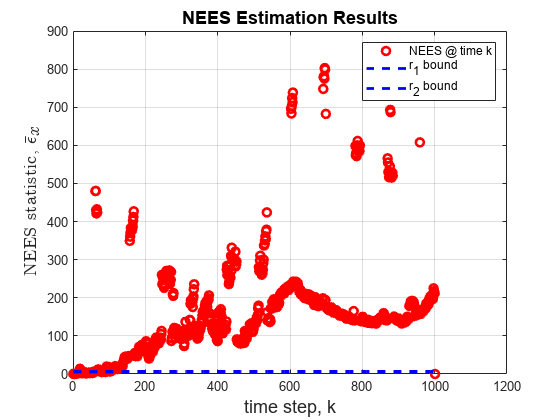


figure(30)
plot(nees_bar,'ro','MarkerSize',6,'LineWidth',2),hold on
plot(r1x*ones(size(nees_bar)),'b--','LineWidth',2)
plot(r2x*ones(size(nees_bar)),'b--','LineWidth',2),hold off
ylabel('NEES statistic, $\bar{\epsilon}_x$','Interpreter','latex', 'FontSize',14)
xlabel('time step, k','FontSize',14)
title('NEES Estimation Results','FontSize',14)
legend('NEES @ time k', 'r_1 bound', 'r_2 bound'),grid on


%NIS Test
epsNISbar = mean(nis_samp,1);
alphaNIS = 0.05;
Nny = N*5;
%%compute intervals:
r1y = chi2inv(alphaNIS/2, Nny )./ N

r1y = 4.1620

r2y = chi2inv(1-alphaNIS/2, Nny )./ N

r2y = 5.9138

f=figure(32)

f =   Figure (32) with properties:

      Number: 32
        Name: ''
       Color: [1 1 1]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


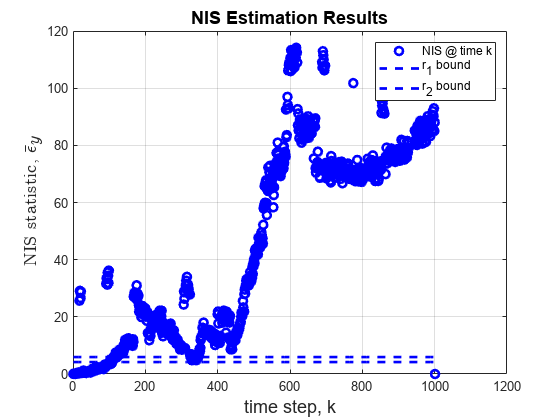

plot(epsNISbar,'bo','MarkerSize',6,'LineWidth',2),hold on
plot(r1y*ones(size(epsNISbar)),'b--','LineWidth',2)
plot(r2y*ones(size(epsNISbar)),'b--','LineWidth',2),hold off
ylabel('NIS statistic, $\bar{\epsilon}_y$','Interpreter','latex','FontSize',14)
xlabel('time step, k','FontSize',14)
title('NIS Estimation Results','FontSize',14)
legend('NIS @ time k', 'r_1 bound', 'r_2 bound'),grid on



x_err = xwn' - x_ekf

x_err =     0.1227    0.2083    0.2745    0.3393    0.3910    0.4282    0.4736    0.4319    0.5081    0.5176    0.5040    0.5025    0.4207    0.4919    0.4275    0.4207    0.2446    0.1693   -0.6375   -0.6472   -0.6622   -0.5860   -0.6344    0.0856    0.0635    0.0987    0.0847    0.0171    0.0268    0.1015    0.1257    0.1453    0.1126    0.1369    0.1317    0.1351    0.0783    0.0022   -0.0339   -0.0172   -0.0599   -0.0168    0.0022   -0.0547   -0.0989   -0.1037   -0.1134   -0.0969   -0.0659   -0.0628
    0.1402    0.0987    0.0789    0.0887    0.1000    0.0882    0.0369   -0.0034   -0.0807   -0.1057   -0.1144   -0.1269   -0.1448   -0.1732   -0.1368   -0.0728    0.0335    0.0731    0.7604    0.9119    0.9950    1.0649    1.1861    0.3854    0.3724    0.3891    0.4766    0.4768    0.5131    0.5312    0.6325    0.5691    0.6258    0.6513    0.6372    0.6684    0.6428    0.6762    0.6140    0.6664    0.6150    0.6030    0.6906    0.7013    0.6922    0.6949    0.7281    0.7066    0.6972 

sig = sqrt(p_a)

sig =     0.0707    0.0784    0.0870    0.0953    0.1031    0.1104    0.1171    0.1233    0.1290    0.1342    0.1389    0.1432    0.1471    0.1506    0.1537    0.1564    0.1588    0.1608    0.1626    0.1640    0.1652    0.1661    0.1669    0.1674    0.1679    0.1682    0.1684    0.1686    0.1688    0.1690    0.1693    0.1697    0.1702    0.1708    0.1716    0.1727    0.1739    0.1754    0.1770    0.1789    0.1810    0.1832    0.1857    0.1883    0.1910    0.1938    0.1966    0.1995    0.2024    0.2053
    0.0707    0.0742    0.0775    0.0807    0.0840    0.0873    0.0906    0.0941    0.0978    0.1016    0.1055    0.1096    0.1139    0.1184    0.1230    0.1277    0.1326    0.1375    0.1426    0.1476    0.1527    0.1578    0.1629    0.1679    0.1728    0.1776    0.1823    0.1868    0.1912    0.1953    0.1993    0.2030    0.2065    0.2097    0.2127    0.2154    0.2179    0.2200    0.2220    0.2236    0.2251    0.2263    0.2272    0.2280    0.2286    0.2290    0.2293    0.2294    0.2295   

sig2p =  + 2*sig

sig2p =     0.1414    0.1567    0.1740    0.1906    0.2062    0.2208    0.2342    0.2466    0.2580    0.2684    0.2779    0.2865    0.2943    0.3012    0.3074    0.3128    0.3176    0.3217    0.3251    0.3280    0.3304    0.3323    0.3338    0.3349    0.3357    0.3363    0.3368    0.3372    0.3376    0.3380    0.3385    0.3393    0.3403    0.3416    0.3433    0.3454    0.3478    0.3507    0.3540    0.3578    0.3619    0.3665    0.3713    0.3765    0.3819    0.3875    0.3932    0.3990    0.4049    0.4107
    0.1414    0.1483    0.1550    0.1615    0.1680    0.1746    0.1813    0.1883    0.1955    0.2031    0.2110    0.2193    0.2279    0.2368    0.2460    0.2555    0.2652    0.2751    0.2851    0.2953    0.3055    0.3156    0.3257    0.3357    0.3456    0.3552    0.3646    0.3736    0.3823    0.3906    0.3985    0.4060    0.4130    0.4194    0.4254    0.4308    0.4357    0.4401    0.4439    0.4473    0.4501    0.4525    0.4544    0.4560    0.4571    0.4580    0.4585    0.4589    0.4591 

sig2n =  - 2*sig

sig2n =    -0.1414   -0.1567   -0.1740   -0.1906   -0.2062   -0.2208   -0.2342   -0.2466   -0.2580   -0.2684   -0.2779   -0.2865   -0.2943   -0.3012   -0.3074   -0.3128   -0.3176   -0.3217   -0.3251   -0.3280   -0.3304   -0.3323   -0.3338   -0.3349   -0.3357   -0.3363   -0.3368   -0.3372   -0.3376   -0.3380   -0.3385   -0.3393   -0.3403   -0.3416   -0.3433   -0.3454   -0.3478   -0.3507   -0.3540   -0.3578   -0.3619   -0.3665   -0.3713   -0.3765   -0.3819   -0.3875   -0.3932   -0.3990   -0.4049   -0.4107
   -0.1414   -0.1483   -0.1550   -0.1615   -0.1680   -0.1746   -0.1813   -0.1883   -0.1955   -0.2031   -0.2110   -0.2193   -0.2279   -0.2368   -0.2460   -0.2555   -0.2652   -0.2751   -0.2851   -0.2953   -0.3055   -0.3156   -0.3257   -0.3357   -0.3456   -0.3552   -0.3646   -0.3736   -0.3823   -0.3906   -0.3985   -0.4060   -0.4130   -0.4194   -0.4254   -0.4308   -0.4357   -0.4401   -0.4439   -0.4473   -0.4501   -0.4525   -0.4544   -0.4560   -0.4571   -0.4580   -0.4585   -0.4589   -0.4591 

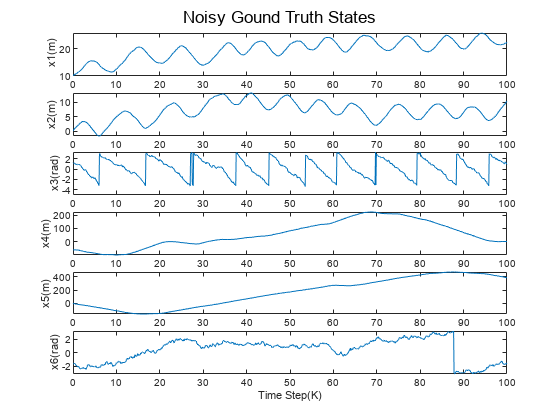


%plot noisy ground truth and measurements
figure(33)
subplot(6,1,1),plot(t, xwn(:,1)),ylabel(' x1(m)');
subplot(6,1,2),plot(t, xwn(:,2)),ylabel('x2(m)');
subplot(6,1,3),plot(t, xwn(:,3)),ylabel('x3(rad)');
subplot(6,1,4),plot(t, xwn(:,4)),ylabel('x4(m)');
subplot(6,1,5),plot(t, xwn(:,5)),ylabel('x5(m)');
subplot(6,1,6),plot(t, xwn(:,6)),ylabel('x6(rad)');
xlabel('Time Step(K)');
sgtitle("Noisy Gound Truth States")

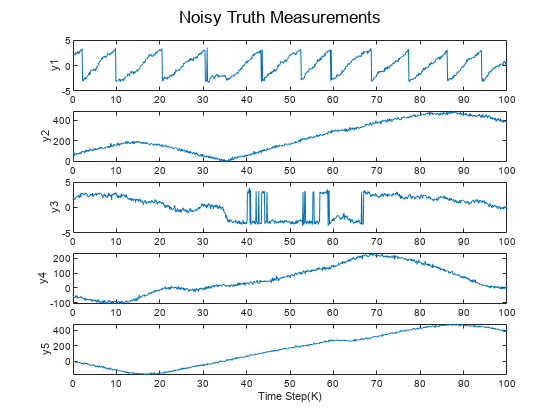


figure(34)
subplot(5,1,1),plot(t, ywn(1,:)),ylabel('y1');
subplot(5,1,2),plot(t, ywn(2,:)),ylabel('y2');
subplot(5,1,3),plot(t, ywn(3,:)),ylabel('y3');
subplot(5,1,4),plot(t, ywn(4,:)),ylabel('y4');
subplot(5,1,5),plot(t, ywn(5,:)),ylabel('y5');
xlabel('Time Step(K)');
sgtitle("Noisy Truth Measurements")

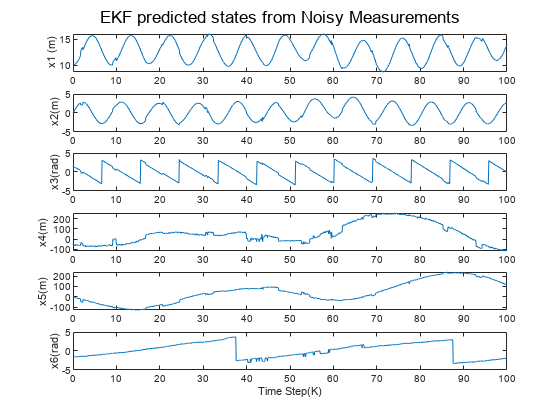


%Plot EKF state prediction for simulated Y
figure(35)
subplot(6,1,1),plot(t,x_ekf(1,:)),ylabel(' x1 (m)');
subplot(6,1,2),plot(t, x_ekf(2,:)),ylabel(' x2(m)');
subplot(6,1,3),plot(t, x_ekf(3,:)),ylabel('x3(rad)');
subplot(6,1,4),plot(t,x_ekf(4,:)),ylabel('x4(m)');
subplot(6,1,5),plot(t, x_ekf(5,:)),ylabel('x5(m)');
subplot(6,1,6),plot(t,x_ekf(6,:)),ylabel('x6(rad)');
xlabel('Time Step(K)');
sgtitle("EKF predicted states from Noisy Measurements");

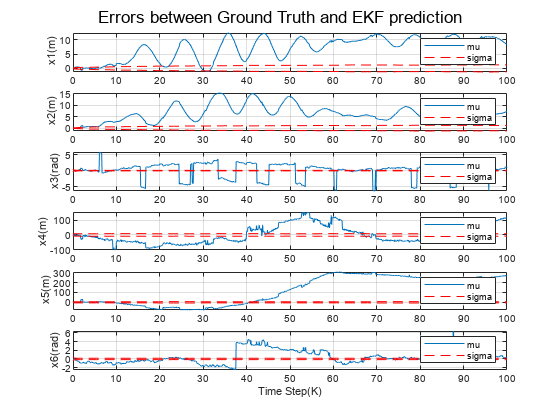


%Plot Errors vs time
figure(36)
subplot(6,1,1),plot(t,x_err(1,:)),ylabel(' x1(m)')
hold on
plot(t,sig2p(1,:),'r--'),grid on
plot(t,sig2n(1,:),'r--'),grid on
legend("mu","sigma")
hold off;
subplot(6,1,2),plot(t, x_err(2,:)),ylabel(' x2(m)'),hold on
plot(t,sig2p(2,:),'r--'),grid on
plot(t,sig2n(2,:),'r--'),grid on
legend("mu","sigma")
hold off;
subplot(6,1,3),plot(t, x_err(3,:)),ylabel('x3(rad)'),hold on
plot(t,sig2p(3,:),'r--'),grid on
plot(t,sig2n(3,:),'r--'),grid on
legend("mu","sigma")
hold off;
subplot(6,1,4),plot(t,x_err(4,:)),ylabel('x4(m)'),hold on
plot(t,sig2p(4,:),'r--'),grid on
plot(t,sig2n(4,:),'r--'),grid on
legend("mu","sigma")
hold off;
subplot(6,1,5),plot(t,x_err(5,:)),ylabel(' x5(m)'),hold on
plot(t,sig2p(5,:),'r--'),grid on
plot(t,sig2n(5,:),'r--'),grid on
legend("mu","sigma")
hold off;
subplot(6,1,6),plot(t,x_err(6,:)),ylabel('x6(rad)'),hold on
plot(t,sig2p(6,:),'r--'),grid on
plot(t,sig2n(6,:),'r--'),grid on
legend("mu","sigma")
hold off;
xlabel('Time Step(K)');
sgtitle('Errors between Ground Truth and EKF prediction')

%Q7 with Ydata

%LKF

Rkf = Rtrue; %1
%Qkf = 0.5*Qtrue; %2
Qkf = diag([500*0.001,500*0.001,0.01*0.01,500*0.01,500*0.01,0.01*0.01]);
x_all = zeros(6,n);
x_all(:,1) = dx0;
sg = dt*eye(6);
[F, G, H] = linStateMats(xmat(1,:), unom, L, dt);
[F2, G2, H2] = linStateMats(xmat(2,:), unom, L, dt);
Hall = [H;H2];
Rall = blkdiag(Rtrue,Rtrue);
xlkt = zeros(6,n);
xlkt(:,1) = transpose(xmat(1,:)) + x_all(:,1);
%p = inv(transpose(Hall)*inv(Rall)*Hall);
p = 10*Qtrue; %4
p_lkf = zeros(6,n);
p_lkf(:,1) = diag(p);
dy_lkf = zeros(5,n);

for i = 1:1000 
        %prediction step
        x_all(:,i+1) = F*x_all(:,i);
        p = F*p*transpose(F) + sg*Qkf*transpose(sg);
        [F, G, H] = linStateMats(xmat(i+1,:), unom, L, dt);
        ypred = H*x_all(:,i+1);
        K = p*transpose(H)*inv(H*p*transpose(H)+Rkf);
        %measurement update
        x_all(:,i+1) = x_all(:,i+1) + K*((ydata(:,i+1)-yfmat(:,i)) - ypred);
        dy_lkf(:,i) = H*x_all(:,i+1);
        p = (eye(6) - K*H)*p;
        xlkt(:,i+1) = transpose(xmat(i+1,:)) + x_all(:,i+1);
        p_lkf(:,i+1) = diag(p);
end

y_lkf = yfmat+dy_lkf;

sig_lkf = sqrt(p_lkf)
sig2p_lkf = xlkt + 2*sig_lkf
sig2n_lkf = xlkt - 2*sig_lkf



figure(70)
subplot(6,1,1),plot(t, xlkt(1,:)),ylabel('x1(m)')
hold on
plot(t,sig2p_lkf(1,:),'r--'),grid on
plot(t,sig2n_lkf(1,:),'r--'),grid on
legend("mu","sigma")
hold off;
subplot(6,1,2),plot(t, xlkt(2,:)),ylabel('x2(m)')
hold on
plot(t,sig2p_lkf(2,:),'r--'),grid on
plot(t,sig2n_lkf(2,:),'r--'),grid on
legend("mu","sigma")
hold off;
subplot(6,1,3),plot(t, xlkt(3,:)),ylabel('x3(rad)')
hold on
plot(t,sig2p_lkf(3,:),'r--'),grid on
plot(t,sig2n_lkf(3,:),'r--'),grid on
legend("mu","sigma")
hold off;
subplot(6,1,4),plot(t, xlkt(4,:)),ylabel('x4(m)')
hold on
plot(t,sig2p_lkf(4,:),'r--'),grid on
plot(t,sig2n_lkf(4,:),'r--'),grid on
legend("mu","sigma")
hold off;
subplot(6,1,5),plot(t, xlkt(5,:)),ylabel('x5(m)')
hold on
plot(t,sig2p_lkf(5,:),'r--'),grid on
plot(t,sig2n_lkf(5,:),'r--'),grid on
legend("mu","sigma")
hold off;
subplot(6,1,6),plot(t, xlkt(6,:)),ylabel('x6(rad)')
hold on
plot(t,sig2p_lkf(6,:),'r--'),grid on
plot(t,sig2n_lkf(6,:),'r--'),grid on
legend("mu","sigma")
hold off;
xlabel('Time Step(K)');
sgtitle('States from LKF');

t1 = t(1:n-1);
figure(61)
subplot(5,1,1),plot(t1, y_lkf(1,1:n-1)),ylabel(' y1')
hold on
plot(t1,ydata(1,2:n))
legend('Lkf','truth')
hold off;
subplot(5,1,2),plot(t1, y_lkf(2,1:n-1)),ylabel('y2')
hold on
plot(t1,ydata(2,2:n))
legend('Lkf','truth')
hold off;
subplot(5,1,3),plot(t1, y_lkf(3,1:n-1)),ylabel('y3')
hold on
plot(t1,ydata(3,2:n))
legend('Lkf','truth')
hold off;
subplot(5,1,4),plot(t1, y_lkf(4,1:n-1)),ylabel('y4')
hold on
plot(t1,ydata(4,2:n))
legend('Lkf','truth')
hold off;
subplot(5,1,5),plot(t1, y_lkf(5,1:n-1)),ylabel('y5')
hold on
plot(t1,ydata(5,2:n))
legend('Lkf','truth')
hold off;
xlabel('Time Step(K)');
sgtitle("LKF Measurements VS Truth Measurements");

%Q7 with Ydata EKF

p_ek = 5*Qtrue;
x0ek = xnom;
x_ekf = zeros(6,n);
x_ekf(:,1) = x0ek;
p_a = zeros(6,n);
p_a(:,1) = diag(p_ek);
sg = dt*eye(6);
Q_ek = 10*Qtrue;
[F, G, H] = linStateMats(x0ek, unom, L, dt);
Rkf2 = Rtrue;
y_ekf = zeros(5,n);

for i = 1:1000
        %prediction
        [tode, ypk] = ode45(xdotwrap, [0 dt], x0ek);
        xnek = transpose(ypk(end, :)); %%
        xnek(3) = constrainAngle(xnek(3));
        xnek(6) = constrainAngle(xnek(6));
        x_ekf(:,i+1) = xnek;
        x0ek = xnek;
        p_ek = F*p_ek*transpose(F) + sg*Q_ek*transpose(sg);

        %measurement update
        [F, G, H] = linStateMats(xnek, unom, L, dt);
        yk = getY(xnek);
        yk(1) = constrainAngle(yk(1));
        yk(3) = constrainAngle(yk(3));
        eyk = ydata(:,i+1) - yk;
        K = p_ek*transpose(H)*inv(H*p_ek*transpose(H)+Rkf2);
        x_ekf(:,i+1) = x_ekf(:,i+1)+K*eyk; %%
        p_ek = (eye(6) - K*H)*p_ek;
        p_a(:,i+1) = diag(p_ek);
        y_ekf(:,i) = getY(x_ekf(:,i+1));
        y_ekf(1,i) = constrainAngle(y_ekf(1,i));
        y_ekf(3,i) = constrainAngle(y_ekf(3,i));

end

sig = sqrt(p_a)
sig2p = x_ekf + 2*sig
sig2n = x_ekf - 2*sig

figure(62)
subplot(6,1,1),plot(t,x_ekf(1,:)),ylabel(' x1(m)')
hold on
plot(t,sig2p(1,:),'r--'),grid on
plot(t,sig2n(1,:),'r--'),grid on
legend("mu","sigma")
hold off;
subplot(6,1,2),plot(t, x_ekf(2,:)),ylabel(' x2(m)'),hold on
plot(t,sig2p(2,:),'r--'),grid on
plot(t,sig2n(2,:),'r--'),grid on
legend("mu","sigma")
hold off;
subplot(6,1,3),plot(t, x_ekf(3,:)),ylabel(' x3(rad)'),hold on
plot(t,sig2p(3,:),'r--'),grid on
plot(t,sig2n(3,:),'r--'),grid on
legend("mu","sigma")
hold off;
subplot(6,1,4),plot(t,x_ekf(4,:)),ylabel(' x4(m)'),hold on
plot(t,sig2p(4,:),'r--'),grid on
plot(t,sig2n(4,:),'r--'),grid on
legend("mu","sigma")
hold off;
subplot(6,1,5),plot(t,x_ekf(5,:)),ylabel('x5(m)'),hold on
plot(t,sig2p(5,:),'r--'),grid on
plot(t,sig2n(5,:),'r--'),grid on
legend("mu","sigma")
hold off;
subplot(6,1,6),plot(t,x_ekf(6,:)),ylabel('x6(rad)'),hold on
plot(t,sig2p(6,:),'r--'),grid on
plot(t,sig2n(6,:),'r--'),grid on
legend("mu","sigma")
hold off;
xlabel('Time Step(K)');
sgtitle('States from EKF')


t1 = t(1:n-1);
figure(63)
subplot(5,1,1),plot(t1, y_ekf(1,1:n-1)),ylabel(' y1')
hold on
plot(t1,ydata(1,2:n))
legend('Ekf','truth')
hold off;
subplot(5,1,2),plot(t1, y_ekf(2,1:n-1)),ylabel('y2')
hold on
plot(t1,ydata(2,2:n))
legend('Ekf','truth')
hold off;
subplot(5,1,3),plot(t1, y_ekf(3,1:n-1)),ylabel('y3')
hold on
plot(t1,ydata(3,2:n))
legend('Ekf','truth')
hold off;
subplot(5,1,4),plot(t1, y_ekf(4,1:n-1)),ylabel('y4')
hold on
plot(t1,ydata(4,2:n))
legend('Ekf','truth')
hold off;
subplot(5,1,5),plot(t1, y_ekf(5,1:n-1)),ylabel('y5')
hold on
plot(t1,ydata(5,2:n))
legend('Ekf','truth')
hold off;
xlabel('Time Step(K)');
sgtitle("EKF Measurements VS Truth Measurements");

function trp = constrainAngle(arf)
trp = arf;
while trp > pi
    trp = trp - (2*pi);
end
while trp < -pi
    trp = trp + (2*pi);
end
end

function [F, G, H] = linStateMats(x, u, L, dt)

A = [0 0 -u(1)*sin(x(3)), 0, 0, 0;
    0 0 u(1)*cos(x(3)), 0 0 0;
    0 0 0 0 0 0;
    0 0 0 0 0 -u(3)*sin(x(6));
    0 0 0 0 0 u(3)*cos(x(6));
    0 0 0 0 0 0];

B = [cos(x(3)) 0 0 0;
    sin(x(3)) 0 0 0;
    tan(u(2))/L u(1)*sec(u(2))^2/L 0 0;
    0 0 cos(x(6)) 0;
    0 0 sin(x(6)) 0;
    0 0 0 1];

F = eye(size(A)) + A*dt;
G = B*dt;

d14 = x(1) - x(4);
d41 = -d14;
d25 = x(2) - x(5);
d52 = -d25;

H = [d52/(d41^2+d52^2) -d41/(d41^2+d52^2) -1 -d52/(d41^2+d52^2) d41/(d41^2+d52^2) 0;
    d14/sqrt(d14^2+d25^2) d25/sqrt(d14^2+d25^2) 0 d41/sqrt(d14^2+d25^2) d52/sqrt(d14^2+d25^2) 0;
    -d25/(d14^2+d25^2) d14/(d14^2+d25^2) 0 d25/(d14^2+d25^2) -d14/(d14^2+d25^2) -1;
    0 0 0 1 0 0;
    0 0 0 0 1 0];

end

function y1 = getY(x)
    d52 = x(5) - x(2);
    d41 = x(4) - x(1);
    d25 = -d52;
    d14 = -d41;
    y1 = [atan2(d52,d41)-x(3);
         sqrt(d14^2+d25^2);
         atan2(d25,d14)-x(6);
         x(4);
         x(5)];
end
